# The Airy Disk of a Diffraction-limited System

The **Airy Disk** describes the blur arising from an ideal (diffraction-limited) uniformly illuminated, circular aperture. Its name arises from the astronomer, Lord Airy [(George Biddell Airy)](https://en.wikipedia.org/wiki/Airy_disk). This script exposes the code used to calculate and plot the Airy disk for diffraction limited optics.

See also: dlMTF, oiCreate; oiCompute, ieShape, ieDrawShape

Copyright ImagEval Consultants, LLC, 2010.

ieInit

## Establish a Scene and a Diffraction-limited Optics

scene = sceneCreate;
oi    = oiCreate;
oi    = oiCompute(oi,scene); 

% Pull out the optics
optics = oiGet(oi,'optics');

## Select Spatial Samples and a Wavelength for plotting

nSamp = 25; thisWave = 500; units = 'um';

clear fSupport
val = opticsGet(optics,'dlFSupport',thisWave,units,nSamp);
[fSupport(:,:,1),fSupport(:,:,2)] = meshgrid(val{1},val{2});

%Over sample to make a smooth image. This move increases the spatial
%frequency resolution (highest spatial frequency) by a factor of 4.
fSupport = fSupport*4;  


Frequency units here are cycles/micron. The spatial frequency support runs from -Nyquist:Nyquist. With this support, the Nyquist frequency is actually the highest (peak) frequency value. There are two samples per Nyquist, so the sample spacing is 


$$\frac{1}{\left(2*\textrm{peakF}\right)}$$



peakF = max(fSupport(:));
deltaSpace = 1/(2*peakF);

## Calculate the OTF using Diffraction-limited MTF (dlMTF)

otf = dlMTF(oi,fSupport,thisWave,units);

% Derive the psf from the OTF
psf = fftshift(ifft2(otf));

% Make the spatial support for the PSF
clear sSupport
samp = (-nSamp:(nSamp-1));
[X,Y] = meshgrid(samp,samp);
sSupport(:,:,1) = X*deltaSpace;
sSupport(:,:,2) = Y*deltaSpace;

% Calculate the Airy disk
fNumber = opticsGet(optics,'fNumber');

% This is the Airy disk radius, by formula
radius = (2.44*fNumber*thisWave*10^-9)/2 * ieUnitScaleFactor(units);

% Draw a circle at the first zero crossing (Airy disk)
nCircleSamples = 200;
[adX,adY,adZ] = ieShape('circle',nCircleSamples,radius);

## Plot the Diffraction-limited PSF

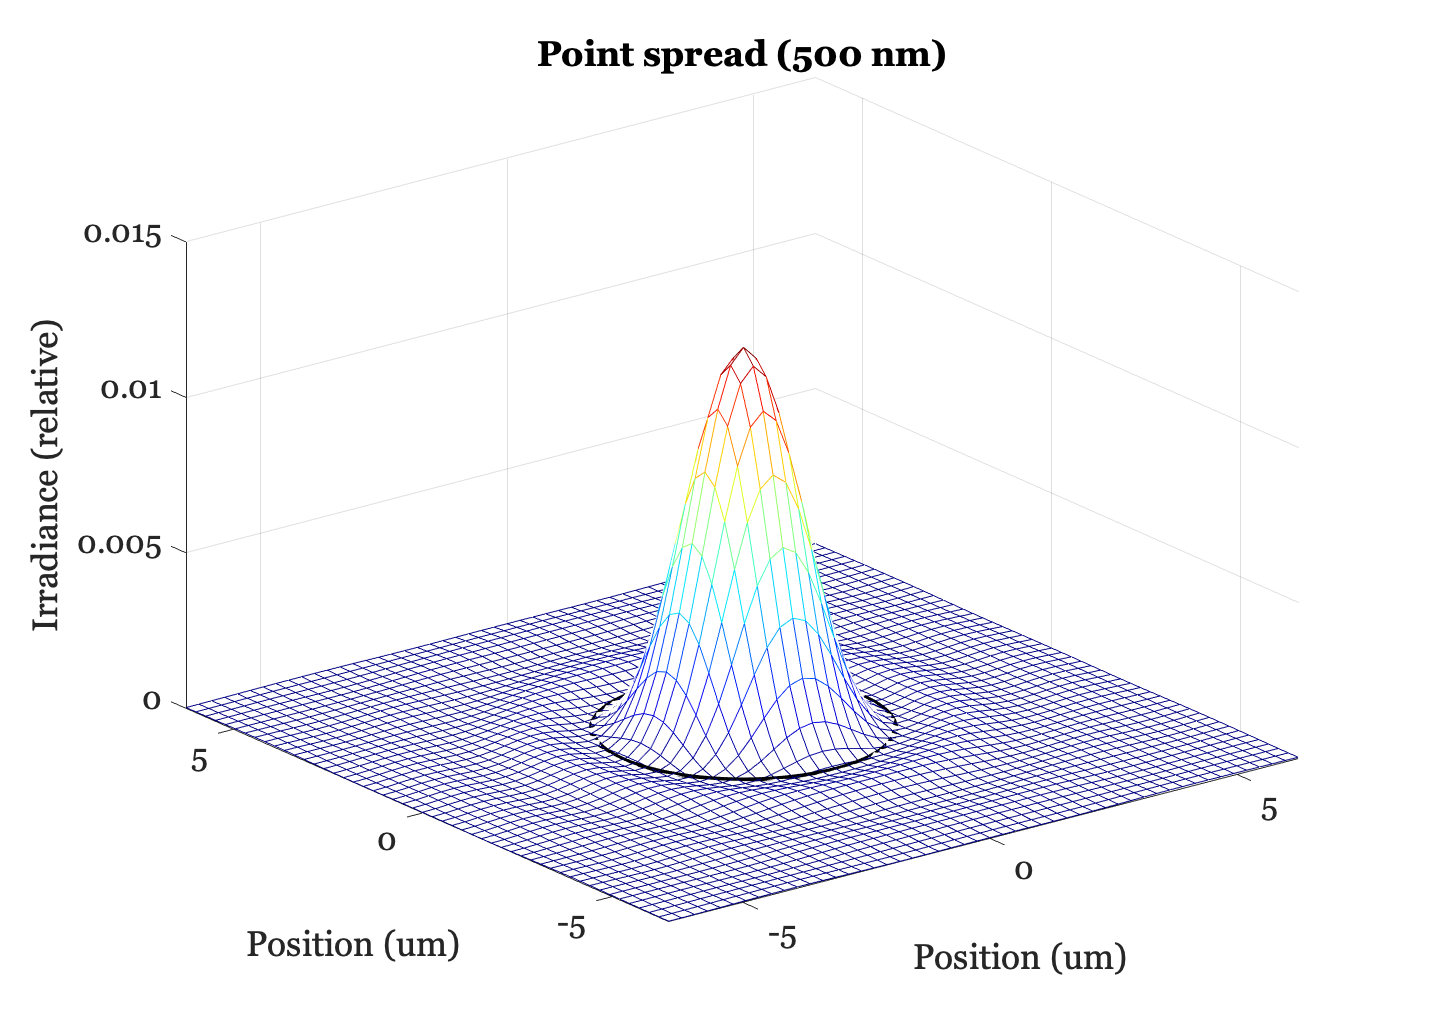

x = sSupport(:,:,1); y = sSupport(:,:,2);
ieNewGraphWin;
mesh(x,y,psf);
colormap(jet)

% Label the graph and draw the Airy disk
ringZ = max(psf(:))*1e-3;
hold on; p = plot3(adX,adY,adZ + ringZ,'k-');
set(p,'linewidth',3); hold off;
xlabel('Position (um)'); ylabel('Position (um)');
zlabel('Irradiance (relative)');
title(sprintf('Point spread (%.0f nm)',thisWave));


% Return the plotted values to the user.  They can retrieve these using
%
% uData = get(gcf,'userData');   %  Note that case sensitivity is ignored
udata.x = x; udata.y = y; udata.psf = psf;
set(gcf,'userdata',udata);

## You'll get the same Result using the ISET Function

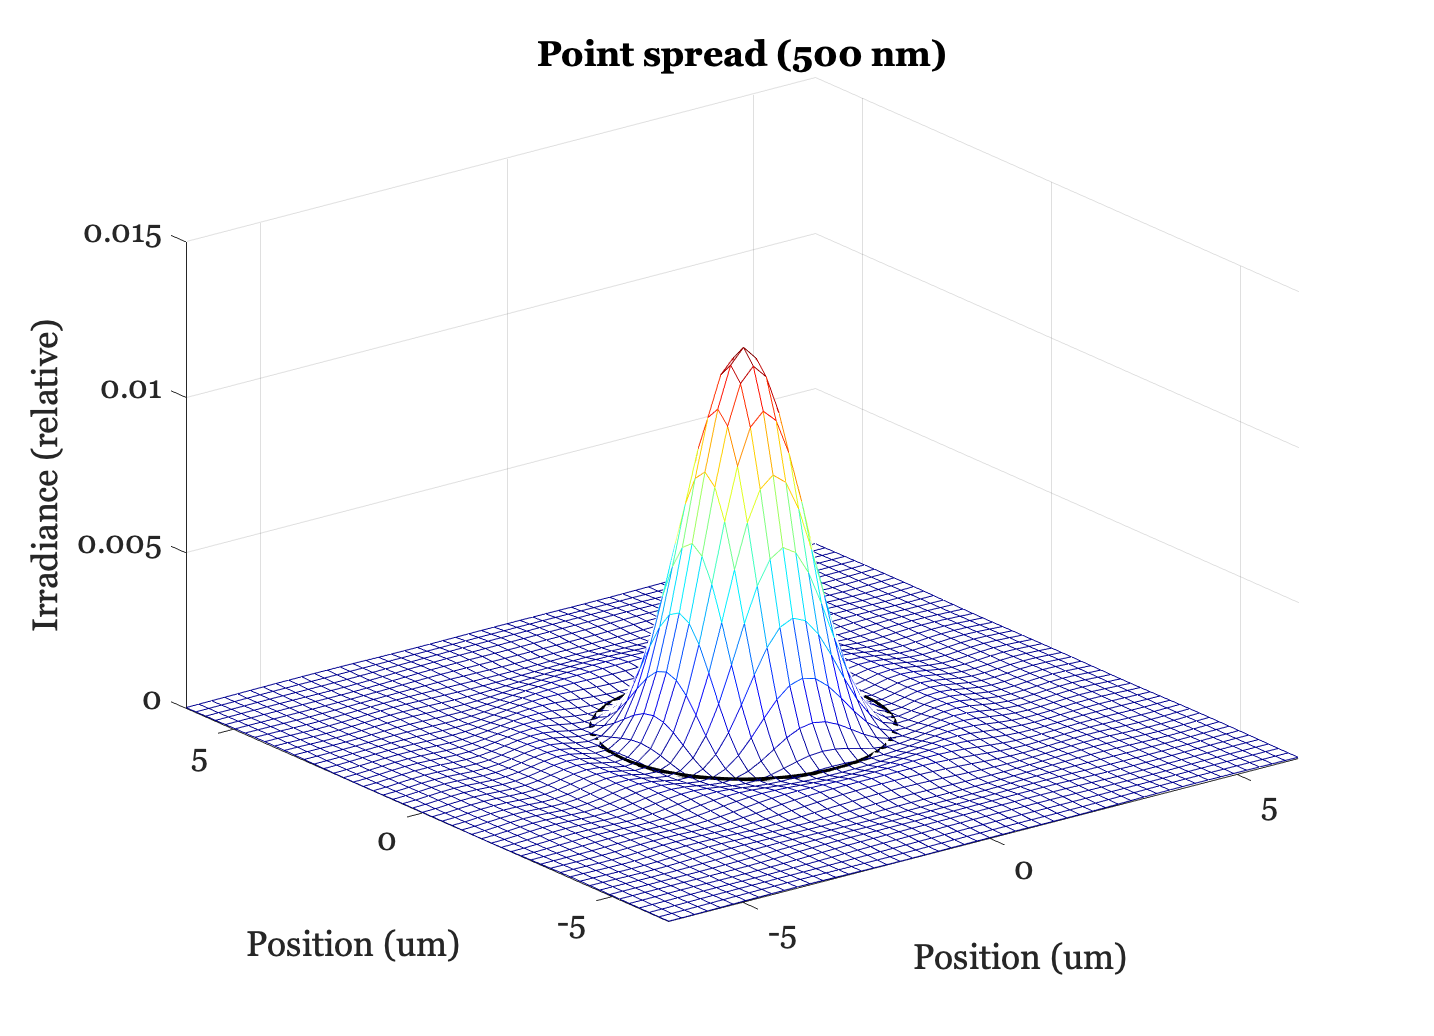

f = oiPlot(oi,'psf',[],500,'um');